# Get Started with Solver-Based Optimize Live Editor Task

This example script helps you to use the solver-based **Optimize** Live Editor task for optimization or equation solving. Modify the script for your own problem.

The script solves a nonlinear optimization problem with nonlinear constraints.

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

clc; clear; close all;

nvar = 4;
SLL_target_dB = -20; % Change this to run the different cases.
lb = [1 1 1 1];
ub = [10 10 10 10];
p_initial = [1 1 1 1];


**Place the **`x0`** value and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

Usually, you place the Optimize Live Editor task into the script by selecting **Task > Optimize** in the **Live Editor** tab, or by selecting **Task > Optimize** in the **Insert** tab. Then you are presented with the following choice (this is only a picture, not the real task):

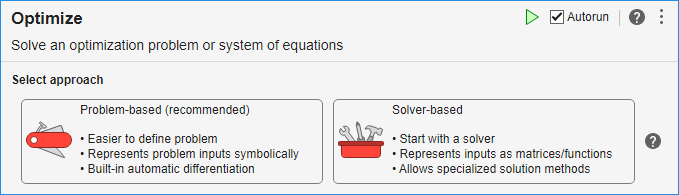

To get the solver-based task, click **Solver-based**.

The following solver-based task has objective and nonlinear constraint functions included. To change these functions, edit the function listings below the task.

To change the constraints, select appropriate constraint types and enter values in the input boxes. You might need to enter values in the section containing `x0` above, and run the section to put values in the workspace.

Run the task by clicking the striped bar to the left, or by choosing **Run** or **Section > Run Section**, or by pressing `Control+Enter`.

gamultiobj stopped because the average change in the spread of Pareto solutions is less than options.FunctionTolerance.


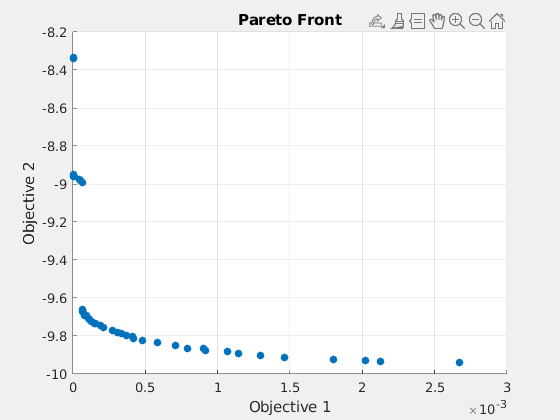

% Pass fixed parameters to objfun
objfun = @(p)SLL_error_and_D(p,SLL_target_dB);

% Set nondefault solver options
options = optimoptions("gamultiobj","PopulationSize",60,"ParetoFraction",0.7,...
    "PlotFcn","gaplotpareto");

% Solve
[solution,objectiveValue] = gamultiobj(objfun,nvar,[],[],[],[],lb,ub,[],[],...
    options);


% Clear variables
clearvars objfun options

save('Pareto_objValue_SLL20.mat', 'objectiveValue');
save('Pareto_sol_SLL20.mat', 'solution');

*.*